# Thomas-Fermi Approximation 

## Thomas-Fermi Model as a Precursor of Density Functional Theory

Thomas-Fermi (TF) model was proposed in 1927, at the time of inception of quantum mechanics, to estimate ground state energy of multi-electron atoms. Main idea is to use electron density as a basic variable and represent energy as a functional of the electron density [*]. Then, the ground state electron density, denoted as $\rho_{TF}(\mathbf{r})$, is obtained by variational principle: it is the density that minimizes the energy functional and corresponding minimal value of the energy is the ground state energy of atom within the TF model. This makes the TF approach a precursor of the Density Functional Theory (DFT). It is the simplest ab initio approach, free of any empirical parameters, to calculate the ground state energy and electron density ([almost fully](https://arxiv.org/abs/physics/0111167)) analytically for any atomic number $Z$. The TF approach captures correctly the leading $Z$ dependence of the ground state energy of neutral atoms for $Z\to \infty$ [1]. For finite, especially small values of $Z$, however, the TF approach is a crude semiclassical formulation. It fails to describe the formation of molecules from atomic constituents [1], however it can be improved with e.g. gradient expansion of kinetic energy (see von Weizsäcker correction that we study in live script: *Orbital-Free DFT)*. Most importantly, the TF model helps us to become familiar with the core two principles on which the DFT is built:

- Treat energy as a functional of the electron density

- Minimize energy functional with respect to electron density to determine the ground state electron density and the ground state energy 

For the orbital-free (or pure) DFT, that we will study in a separate live script, the TF model is recovered as a special limit, allowing us to benchmark the accuracy of our OFDFT numerical code.  

## Thomas-Fermi Approximation for Potential Energy Functional

Hamiltonian of the $N$-electron atom with the nuclear charge $Ze$ and nucleus fixed at the origin (using the Born-Oppenheimer approximation) in the SI system of units is:


$$\hat{H} =\hat{T}+\hat{V}_{e n}+\hat{V}_{e e}  =-\frac{\hbar^2}{2m_e} \sum_{i=1}^{N}  \nabla_{i}^{2}-\frac{Ze^2}{4\pi\epsilon_0}\sum_{i=1}^{N}  \frac{1}{\left| \mathbf{r}_{i} \right|}+\frac{e^2}{2}\frac{1}{4\pi\epsilon_0} \sum_{j=1(j\neq i)}^{N} \sum_{i =1}^{N} \frac{1}{\mid \mathbf{r}_{i}- \mathbf{r}_{j} \mid}, \qquad(1)$$


with the 3D coordinate vector of $i-$th electron $\mathbf{r}_i$ and usual constants: electric charge $e$, [electric constant](https://en.wikipedia.org/wiki/Vacuum_permittivity) - vacuum permittivity $\epsilon_0$, etc.  We will mainly be interested in the neutral atom case of $N=Z$.

The energy functional of this system [*] is represented as a sum of the kinetic and potential terms: $E[\rho]=T[\rho]+V[\rho]$, both yet to be specified. The potential energy functional is further represented as a sum of electron-nucleon and electron-electron interactions: 

$V[\rho]=V_{en}[\rho]+V_{ee}[\rho]\qquad(2)$. 

Note that $V_{ee}$ is present only for $N>1$. Using Dirac's 3D delta function, the single-electron density in $N$-electron state $| \alpha \rangle$ is given by :


$$\rho_{\alpha}( \mathbf{r})=\sum_{i=1}^{N}  \langle \alpha| \delta^3 (\mathbf{\hat r}_i -\mathbf{r}) |\alpha\rangle \qquad(3)$$


and $\rho_{\alpha}(\mathbf{r}) d\mathbf{r}/N$ can be interpreted as a probability of finding $i-$th electron in infinitesimal volume $d\mathbf{r}\equiv d^3\mathbf{r}$ around point $\mathbf{r}$ in state $|\alpha \rangle$.

The single-electron density determines the expectation value of the electron-nucleon interaction potential in arbitrary many-body state, 


$$\langle \alpha| \hat V_{en} |\alpha \rangle=  -\frac{Z e^2}{4 \pi \epsilon_0} \int_{R^3} \frac{ \rho_{\alpha}(\mathbf{r})}{ | \mathbf{r}|} d \mathbf{r} \qquad(4)$$
 

and hence we can immediately obtain the corresponding functional: 


$$V_{en}[\rho]=-\frac{Z e^2}{4 \pi \epsilon_0} \int_{R^3} \frac{ \rho(\mathbf{r})}{ | \mathbf{r}|} d \mathbf{r}. \qquad(5)$$


See derivation of Eq. (4) in the live script *From Many-Body Wave Function Description to DFT.*

Thomas and Fermi obtained the expression for $V_{en}[\rho]$ by calculating the potential energy of electron charge distribution $-e\rho(\bf{r})$ in electrostatic potential of a nucleus that is localized at the origin and has charge distribution $Ze\delta(\mathbf{r'})$, as indicated by a red dot in  Fig. 1. For obtaining expression of $V_{ee}[\rho]$, Thomas and Fermi calculated classical electrostatic Coulomb repulsion energy between different parts of electron cloud such as indicated by dashed circles in Fig. 1: $\frac{e^2}{4\pi\epsilon_0} \frac{\rho\left(\mathbf{r}_1\right)d \mathbf{r}_1 \rho\left(\mathbf{r}_2\right)d \mathbf{r}_2}{\left|\mathbf{r}_1-\mathbf{r}_2\right|}$ and summed up all possible contributions. A cloud of negatively charged electrons, distributed with electric charge density $-e\rho(\bf{r'})$, is depicted in cyan color in Fig. 1. 

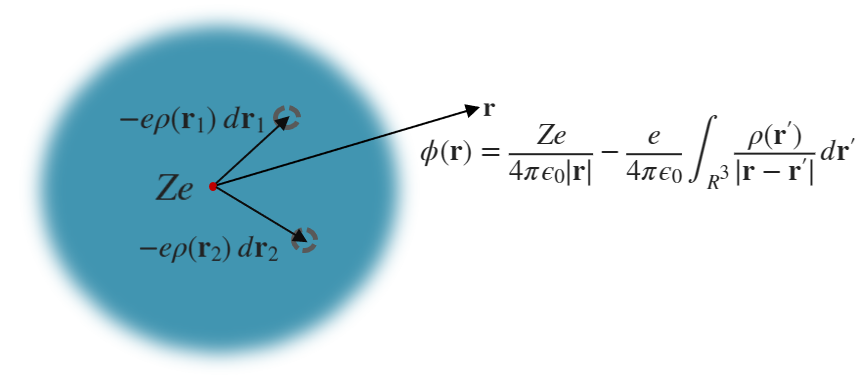

   Figure 1: Distribution of a point nuclear charge (red dot) $Ze\delta(\mathbf{r'})$ and a negatively charged 

                                  electron cloud (cyan) $-e\rho(\mathbf{r'})$. $\phi(\mathbf{r})$ is electrostatic potential created by an atom at point $\mathbf{r}$. 

                                 Dashed circles indicate elementary 3D volumes $d\mathbf{r}_j$ with charges $-e\rho(\mathbf{r}_j)d\mathbf{r}_j$, for $j=1,2$.

Hence, expression of the potential energy functional in the TF model is:   


$$V_{TF}[\rho]=V_{en}[\rho]+V_{ee}^{TF}[\rho] =-Ze^2  \frac{1}{4\pi\epsilon_0}\int_{R^3} \frac{\rho(\mathbf{r})}{|\mathbf{r}|}  d \mathbf{r} + \frac{e^2}{2} \frac{1}{4\pi\epsilon_0} \int_{R^3}\int_{R^3} \frac{\rho\left(\mathbf{r}_1\right) \rho\left(\mathbf{r}_2\right)}{\left|\mathbf{r}_1-\mathbf{r}_2\right|} d \mathbf{r}_1 d \mathbf{r}_2,\qquad(6)$$


with an extra factor of $1/2$ in the last term to avoid double counting, as both integration variables $\mathbf{r}_1$ and $\mathbf{r}_2$ run over the whole $R^3$ space. $V_{ee}^{TF}[\rho]$ is denoted by $J[\rho]$ or $E_H[\rho]$ in the literature and is called Hartree or direct interaction energy functional. It includes nonphysical self-interaction of electrons, which is obvious for $N=1$ case when $V_{ee}=0$ while $V_{ee}^{TF}[\rho] \neq 0$, see Exercise 1 in the live script *From Many-Body Wave Function Description to DFT.* 

In the following, unless we explicitly indicate integration regions, all integrals will be assumed over the whole 3D space and subscript $R^3$ will be omitted. 

## Thomas-Fermi Approximation for Kinetic Energy Functional

Thomas and Fermi constructed the kinetic energy density functional using the local density approximation (LDA). They took the expression of the exact kinetic energy in terms of electron density for a system with homogeneous ground state electron density, after which they assumed the same expression to hold locally for the inhomogeneous system such as atom. Hence, we can expect that the TF approximation for the kinetic energy functional is a reasonable approximation for systems that are only weakly inhomogeneous. 

Let's express the ground-state kinetic energy in terms of the ground state electron density for the simplest homogeneous system of non-interacting electrons in the absence of electron-nucleon interaction (hence described by Hamiltonian $\hat H  =\hat T$ in Eq. (1)), confined to a box of a linear size $l$ with periodic boundary conditions in all 3 directions (3D torus). Single-electron coordinate eigen functions of such system are plane waves


$$\begin{array}{cc}\phi\left(x, y, z\right) =\frac{1}{l^{3 / 2}} e^{i\left(k_x x+k_y y+k_z z\right)}  =\frac{1}{V^{1 / 2}} e^{i \mathbf{k} \cdot \mathbf{r}},& \qquad (7)\\ \end{array}$$


where  periodic boundary conditions in all 3 directions $\psi(r_i+l)=\psi(r_i)$ (where $r_i=x,y,z$ components) require:


$$\begin{array}{cc}k_x=\frac{2 \pi}{l} n_x, \quad k_y=\frac{2 \pi}{l} n_y, \quad k_z=\frac{2 \pi}{l} n_z, \quad n_x, n_y, n_z=0, \pm 1, \pm 2 \cdots& \qquad (8)\\ \end{array}$$
 

The ground state one-body density matrix for the system of even $N$ electrons, with each plane wave state from $|\mathbf{k}|=0$ up to $|\mathbf{k} |= k_F$ occupied by spin up and spin down electrons, is (see Exercise 1): 


$$\rho_0\left(\mathbf{r}, \mathbf{r'}\right) =2 \sum_{i=1}^{N/2 } \phi^*_i\left(\mathbf{r}\right) \phi_i\left(\mathbf{r'}\right) = \frac{2}{V} \sum_{ |\mathbf{k}|=0}^{ |\mathbf{k}| \le k_F} e^{-i \mathbf{k} \cdot\left(\mathbf{r}-\mathbf{r'}\right)}. \qquad (9)$$


For large number of occupied states (large $N$) and in the limit $l\to \infty$, the sum over the $k$- vectors in Eq. (9) can be replaced by an integral with the volume element in 3D $k$-space: $\left(\frac{2\pi}{l}\right)^3=d\mathbf{k}$, giving


$$\rho_0\left(\mathbf{r}, \mathbf{r'}\right) =\frac{1}{4 \pi^3} \int^{|\mathbf{k}|\le k_F} e^{-i \mathbf{k} \cdot\left( \mathbf{r}-\mathbf{r'}\right)} d \mathbf{k}  =\frac{1}{4 \pi^3} \int_0^{k_F} k^2 d k \int \int e^{-i\mathbf{k} \cdot( \mathbf{r}-\mathbf{r'})} \sin \theta d \theta d \phi. \qquad (10)$$


Since $\rho_0(\mathbf{r})=\displaystyle\sum_{i=1}^{N}  \langle \Psi_0 | \delta^3 (\mathbf{\hat r}_i -\mathbf{r})  | \Psi_0\rangle=\rho_0(\mathbf{r},\mathbf{r})$ and $e^{i \mathbf{k} \cdot (\mathbf{r} -\mathbf{r'}) }=1$ for $\mathbf{r}=\mathbf{r'}$, we get 


$$\begin{array}{cc}\rho_0(\mathbf{r})=\frac{k_F^3}{3\pi^2}, \qquad \text{or} \qquad k_F(\mathbf{r})=\left[3 \pi^2 \rho_0(\mathbf{r})\right]^{1 / 3}.& \qquad (11)\\ \end{array}$$


Note that Eq. (11) was obtained for $\hat H  =\hat T$ in Eq. (1), when $\rho_0$ does not depend on $\mathbf{r}$. We assume that the same relation between $k_F$ and local ground state electron density holds when $\rho_0$ is (weakly) non-uniform. One can take $k_F(\mathbf{r})=\left[3 \pi^2 \rho_0(\mathbf{r})\right]^{1 / 3}$ as a definition of the local Fermi momentum in case of the non-uniform ground state electron density. 

Since the contribution in kinetic energy from the occupied $j$-th plane wave is given by $2\frac{\hbar^2}{2m_e}\left(\mathbf{k}_j \cdot \mathbf{k}_j\right)$, with the overall factor of $2$ due to 2 spin components, we can write the ground state value of the kinetic energy per unit volume as


$$\begin{array}{cc}\langle \Psi_0|\hat T/V|\Psi_0 \rangle=\frac{\hbar^2}{m_eV} \sum_{j} \mathbf{k}_j \cdot \mathbf{k}_j = \frac{\hbar^2}{8 m_e \pi^3} \int(\mathbf{k} \cdot \mathbf{k}) d \mathbf{k} =\frac{\hbar^2 }{8m_e \pi^3} \int_0^{k_F} k^4 d k \int_0^\pi \sin \theta d \theta \int_0^{2 \pi} d \phi=\frac{ k^5_F}{10 \pi^2}  \frac{\hbar^2}{m_e} .& \qquad (12)\\ \end{array}$$


Using  Eq. (11) we obtain from Eq. (12) 


$$\begin{array}{cc}T_0=\langle \Psi_0|\hat T|\Psi_0\rangle =    C_F   \rho_0^{5 / 3} V = C_F    \int \rho_0^{5 / 3} d \mathbf{r}=T_0[\rho_0],\\ \end{array} \qquad(13)$$


where $C_F=(3 / 10)\left(3 \pi^2\right)^{2 / 3}\frac{\hbar^2}{m_e}\simeq2.8712 \frac{\hbar^2}{m_e}$. 

Thomas and Fermi extrapolated the expression of the ground state kinetic energy in terms of the electron density, obtained for the system with the uniform ground state electron density $\rho_0(\mathbf{r})=N/V$, to the case of interacting electrons inside atoms, with clearly non-uniform electron density, by replacing the known constant density $\rho_0$ in Eq. (13) by local $\mathbf r$ - dependent one $\rho(\mathbf{r})$ (which is unknown and will be determined variationally below). This practice is known as the LDA or the TF approximation for kinetic energy and leads to the TF kinetic energy functional:


$$\begin{array}{cc}T_{T F}[\rho]=T_0[\rho]=C_F \int \rho(\mathbf{r})^{5 / 3} d \mathbf{r}.& \qquad (14)\\ \end{array}$$


## Thomas-Fermi Approximation for Energy Functional

With the potential energy functional $V_{TF}[\rho]$ in Eq. (6) and the kinetic energy functional $T_{TF}[\rho]$ in Eq. (14), the total energy functional of an *N*-electron atom with atomic number $Z$, in the [Hartree system of atomic units](https://en.wikipedia.org/wiki/Hartree_atomic_units) (with $\hbar= m_e=e=1$and hence $C_F=(3 / 10)\left(3 \pi^2\right)^{2 / 3} \simeq 2.8712$ and $4\pi\epsilon_0=1$), is written in the TF model as


$$\begin{array}{cc}E[\rho]=T_{TF}[\rho]+V_{TF}[\rho]=C_F \int \rho(\mathbf{r})^{5 / 3} d \mathbf{r}-Z\int \frac{\rho(\mathbf{r})}{|\mathbf{r}|}  d \mathbf{r} + \frac{1}{2} \int\int \frac{\rho\left(\mathbf{r}\right) \rho\left(\mathbf{r'}\right)}{\left|\mathbf{r}-\mathbf{r'}\right|} d \mathbf{r} d \mathbf{r'},& \qquad (15)\\ \end{array}$$


with a constraint on electron density: 


$$\begin{array}{cc}\int \rho(\mathbf{r}) d\mathbf{r} = N.& \qquad (16)\\ \end{array}$$


In atomic units the distance $r=|\mathbf{r}|$ is measured in the units of Bohr radius $a_0$, and energy - in units of Hartree energy $E_h$. We will study here the TF model for $N=Z$,  i.e. the neutral atom case. See Ref. [1] and references therein for rigorous treatment of the TF model for any $Z$ and $N$. 

A generic $N$- electron system such as molecules, or crystals, with $N_n$ immobile nuclear charges $Z_I$ distributed at positions $\mathbf{R}_I$ (hence within the Born-Oppenheimer approximation) is described by the following Hamiltonian 


$$\begin{array}{cc}\hat{H} =\hat{T}+\hat{V}_{e n}+\hat{V}_{e e}  +E_{nn}=-\frac{1}{2} \sum_{i}^{N} \nabla_{i}^{2}-\sum_{i=1}^{N} \sum_{I=1}^{N_{n}} \frac{Z_{I}}{\left|\mathbf{r}_{i}-\mathbf{R}_{I}\right|}+\frac{1}{2} \sum_{j=1( j\neq i)}^{N} \sum_{i=1}^{N} \frac{1}{\mid \mathbf{r}_{i}-\mathbf{r}_{j} \mid} +E_{nn},&\\ \end{array}$$


with nucleus-nucleus Coulomb repulsion potential energy $E_{nn}=\displaystyle \sum^{N_n}_{I'>I} \sum^{N_n}_{I=1} \frac{Z_IZ_{I'} }{|\mathbf{R}_I -\mathbf{R}_{I'} |  }$. The Thomas-Fermi approximation to energy functional for such systems is defined as: 


$$\begin{array}{cc}E[\rho]=C_F \int \rho(\mathbf{r})^{5 / 3} d \mathbf{r}+\int V_{ext} (\mathbf{r}) {\rho(\mathbf{r})}  d \mathbf{r} + \frac{1}{2} \int\int \frac{\rho\left(\mathbf{r}\right) \rho\left(\mathbf{r'}\right)}{\left|\mathbf{r}-\mathbf{r'}\right|} d \mathbf{r} d \mathbf{r'} +E_{nn},& \\ \end{array}$$


where $V_{ext}(\mathbf{r}) =-\displaystyle\sum^{N_n}_{I=1}\frac{Z_{I}}{\left|\mathbf{r}-\mathbf{R}_{I}\right|}$. A single atom case Eq. (15) is recovered for $N_n=1$, $Z_1=Z$, $E_{nn}=0$ and $\mathbf{R}_1=0$. TF approximation is too crude to describe formation of a bound state of two atoms into a molecule, since minimization of $E[\rho]$ is achieved when two nucleus are as far as possible from each other, see Ref. [1]. 

Readers will better understand the TF model's validity, what does expression of energy functional in Eq. (15) capture and what does it neglect, after familiarizing themselves with the DFT and especially the orbital-free implementation of the DFT that we present in separate live scripts. 

## Thomas-Fermi Electron Density 

Our aim below is to search for the density profile $\rho_{_{TF}}(\mathbf{ r})$, such that, it satisfies constraint in Eq. (16), and hence it indeed describes $N$-electron system, and when we substitute $\rho(\mathbf {r})=\rho_{_{TF}}(\mathbf {r})$ in the energy functional Eq. (15), it gives us the minimum for the functional: $E[\rho_{TF}]= \min \Big\{ E[\rho]$ with: $\rho(\mathbf{r})\ge 0$ everywhere, $\int \rho(\mathbf{r}) \mathrm{d} \mathbf{r} =N$, and $\int\rho^{5/2}(\mathbf{r}) d\mathbf{r}<\infty \Big\}$, or: $\rho_{_{TF}}(\mathbf{r})=\arg\min E[\rho]$. We will denote the minimum of the TF functional, or in other words the ground state energy of the TF model, by $E_{TF} \equiv \min \big\{E[\rho]\big\}$, hence by definition of $\rho_{_{TF}}(\mathbf{ r})$ we have: $E[\rho_{TF}]=E_{TF}$. 

To implement the constraint in Eq. (16), as a common practice in constrained optimization problems, we introduce a Lagrange multiplier $\mu$ as an independent parameter that controls the total number of electrons which becomes a functional of the density $N[\rho]$, given below in Eq. (A2). We pass from energy functional to the "Lagrange" functional (pass from canonical to grand-canonical description) with $\mathcal{L}[\rho]=E[\rho] -  \mu\left( N[\rho]-N\right)$ (see Appendix 1), and the proper normalization of density as in Eq. (16) is imposed by $\partial {\cal L} / \partial \mu=0$. Solving the Euler-Lagrange equation, obtained by putting [functional derivative](https://en.wikipedia.org/wiki/Functional_derivative) $\delta \mathcal{L}/\delta \rho (\mathbf{r}) =0$ (using $\delta\rho( \mathbf{r'}) /\delta \rho (\mathbf{r}) =\delta^3(\mathbf{r}-\mathbf{r'})$), leads to the equation for the "equilibrium" density i.e. the TF density profile: 


$$\frac{5}{3} C_{F} \rho_{_{TF}}^{2 / 3}(\mathbf{r})-\frac{Z}{|\mathbf{r}|}+\int \frac{\rho_{_{TF}}\left(\mathbf{r}^{\prime}\right)}{\left|\mathbf{r}-\mathbf{r}^{\prime}\right|} d \mathbf{r}^{\prime} -\mu=0 . \qquad (17)$$


By definition of the TF density: $\delta \mathcal{L}[\rho_{_{TF}}]  =0$, leading for fixed $Z$ to (see  Appendix 2 for details) 


$$\delta E_{TF}  =\mu \delta N. \qquad (18)$$


Hence, $\mu$ is a rate of change of the lowest ("the ground state") energy of the TF model with changing the total number of electrons. This is also a definition of the zero temperature chemical potential. 

For neutral atoms, we denote the chemical potential as $\mu_{_{NA}}$. We will assume that for neutral atoms $\mu_{_{NA}}=0$ for any $Z$ and follow computations as presented below. Afterwards we will show that $\int \rho_{_{TFNA}} (\mathbf{r}) d\mathbf{r}=Z$, where the TF density for neutral atoms is denoted as $\rho_{_{TFNA}}(\mathbf{r})$, hence proving (see also Exercise 2) that our assumption of $\mu_{NA}=0$ is correct:


$$\int \rho_{_{TFNA}} (\mathbf{r}) d\mathbf{r}=Z, \to \mu_{_{NA}}=0. \qquad (19)$$


Substituting $\mu=\mu_{NA}=0$ in the TF Eq. (17) for a neutral atom gives us:


$$\begin{array}{cc}\frac{5}{3}C_{F} \rho_{_{TFNA}}^{2 / 3}(\mathbf{r})=\frac{Z}{|\mathbf{r}|}-\int \frac{\rho_{_{TFNA}}\left(\mathbf{r}^{\prime}\right)}{\left|\mathbf{r}-\mathbf{r}^{\prime}\right|} d \mathbf{r}^{\prime}.& \qquad (20)\\ \end{array}$$


Next, we denote by $\phi(\mathbf{r})$ the electrostatic potential created by the electric charge distribution of the atom in the ground state (we remind that in atomic units $e/(4\pi\epsilon_0) =1$): 


$$\phi(\mathbf{r})=\frac{Z}{|\mathbf{r}|}-\int \frac{\rho_{_{TFNA}}\left(\mathbf{r}^{\prime}\right)}{\left|\mathbf{r}-\mathbf{r}^{\prime}\right|} d \mathbf{r}^{\prime},\qquad (20b)$$


as shown in  Fig. 1.  From Eqs. (20) and (20b), we express $\rho_{_{TFNA}}(\mathbf{r})$ by $\phi(\mathbf{r})$,


$$\begin{array}{cc}\rho_{_{TFNA}}(\mathbf{r})=\left(\frac{3}{5C_F}\right)^{3 / 2}[\phi(\mathbf{r})]^{3 / 2}.& \qquad (21)\\ \end{array}$$


Applying 3D Laplacian $\nabla^2$ to both sides of Eq. (20b) we obtain:


$$\begin{array}{cc}\nabla^2 \phi(\mathbf{r})=4 \pi \rho_{_{TFNA}}(\mathbf{r})-4 \pi Z \delta^3(\mathbf{r}).& \qquad (22)\\ \end{array}$$


In deriving Eq. (22) we used the well known formula relating 3D Laplacian of inverse distance with 3D Dirac's delta function: $\nabla^2 (1/r)=-4\pi \delta^3(\mathbf{r})$, $\nabla^2 (1/|\mathbf{r}-\mathbf{r'}|)=-4\pi \delta^3(\mathbf{r}-\mathbf{r'})$, see the derivation in hint to Exercise 3. 

We use Eq. (21) to arrive from Eq. (22) to


$$\begin{array}{cc}\nabla^2 \phi(\mathbf{r})=4 \pi\left(\frac{3}{5C_F}\right)^{3 / 2}[\phi(\mathbf{r})]^{3 / 2}-4 \pi Z \delta^3(\mathbf{r}).& \qquad (23)\\ \end{array}$$
 

In case of spherically symmetric electron distribution, like the ground state of an atom with filled subshells, $\rho_{TFNA}(\mathbf{r})=\rho_{TFNA}(r)$, hence $\phi(\mathbf{r})$ also should depend only on $r$. This can be seen in Eq. (21): if its left-hand-side is function of only $r$ so should be its right-hand-side. To solve Eq. (23), that is a differential equation for $\phi(\mathbf{r})$, we write


$$\begin{array}{cc}\phi(\mathbf{r})=\phi(r)=\frac{Z}{r} \tilde \chi(r),& \qquad (24)\\ \end{array}$$


and hence: 


$$\nabla^2 \phi( r)=Z\nabla^2 \Big(\frac{\tilde \chi(r)}{r}\Big). \qquad(25)$$


Then Eq. (23), by using Eq. (24), gives us:


$$Z\nabla^2 \Big(\frac{\tilde \chi(r)}{r}\Big)=4 \pi\left(\frac{3}{5C_F}\right)^{3 / 2} \frac{Z^{3 / 2}}{r^{3 / 2}}[\tilde \chi(r)]^{3 / 2}-4\pi Z \delta^3(\mathbf{r}).\qquad (26)$$


To solve the differential equation (26) we will use the following relation (see Exercise 3):


$$\nabla^2 \Big( \frac{\tilde \chi(r)}{r}\Big)=\frac{1}{r}\frac{d^2 \tilde \chi(r)}{d r^2} -4 \pi \tilde \chi(0)\delta^3(\mathbf{r}). \qquad (27)$$


We confirm that for $r>0$ we have $\frac{1}{r^{2}} \frac{\partial}{\partial r}\left(r^{2} \frac{\partial}{\partial r}\right)  \Big( \frac{\tilde \chi(r)}{r}\Big)=\frac{1}{r}\frac{d^2 \tilde \chi(r)}{d r^2}$ using symbolic calculation:

syms r real positive         % define real, positive symbolic variable r
syms chi_tilde(r)            % define symbolic function  
simplify(1/r^2*diff(r^2*diff(chi_tilde/r)))    

$$ans(r) = \frac{\frac{\partial^{2}}{\partial r^{2}}\tilde{\chi }\left(r\right)}{r}$$

To obtain the singular (the delta function) contribution at $r=0$ in Eq. (27) see the derivation in hint to Exercise 3.

We will next require  


$$\tilde \chi(0)=1 \qquad (28)$$
 

in order to obtain from Eq. (26) (by using Eqs. (27) and (28)):


$$\begin{array}{cc}\frac{d^2 \tilde \chi(r)}{d r^2}=4 \pi\left(\frac{3}{5C_F}\right)^{3 / 2} \frac{Z^{1 / 2}}{r^{1 / 2}}[\tilde \chi(r)]^{3 / 2}.& \qquad (29)\\ \end{array}$$


From the definition of the electrostatic potential created by an atom in the ground state Eq. (20b), we have for $r\to 0$:


$$\phi(r ) = \frac{Z}{r}\Big(1-\frac{4\pi r}{Z} \cdot\int_0^{\infty} \rho_{_{TFNA}}(r')r'dr'  +o(r)\Big), \qquad(30)$$


where $o(r)$ indicates higher power than linear in $r$ terms. Comparing $\phi(r)=\frac{Z}{r}\tilde \chi(r)$ with Eq. (30), we deduce that when $r\to 0$


$$\tilde \chi(r ) = 1-\frac{4\pi r}{Z} \cdot\int_0^{\infty} \rho_{_{TFNA}}(r')r'dr'+o(r ) \qquad (31)$$


and hence we recover $\tilde \chi(0)=1$ boundary condition Eq. (28), which, in its turn, leads to: $\displaystyle \int_0^{\infty} \rho_{_{TFNA}}(r )r^2dr=\frac{Z}{4\pi}$ - neutrality condition, see  Exercise 2.

Since $4\pi \int_0^{\infty} \rho_{_{TFNA}}(r )r^2dr=Z$ is finite, from $\rho_{_{TFNA}}(\mathbf{r})=\left(\frac{3}{5C_F}\right)^{3 / 2}[Z \tilde \chi(r)/r]^{3 / 2}$ and from the fact that density $\rho_{_{TFNA}}( r)\ge 0$ and hence $\tilde \chi (r)\ge 0$ for all $r$, we conclude that $\tilde \chi$ must vanish for $r\to \infty$ sufficiently fast, see Eq. (37) below, hence $\tilde \chi(\infty)=0$. 

Finally, if we let


$$\begin{array}{cc}x=\alpha r, \quad \alpha=Z^{1 / 3}(4 \pi)^{2 / 3}\left(\frac{3}{5C_F}\right)\simeq 1.1295 Z^{1 / 3}& \qquad (32)\\ \end{array}$$
 

we obtain from Eq. (29) **a universal, **$Z$**- independent differential equation** for function


$$\chi(x)=\tilde \chi(r(x))=\tilde \chi(x/\alpha) , \qquad (32b)$$


with $r(x)=x/\alpha$,


$$\begin{array}{cc}\frac{d^2 \chi(x)}{d x^2}=\frac{ \chi^{3/2}(x)}{x^{1 / 2}}.& \qquad (33)\\ \end{array}$$


The boundary conditions that we have just established for $\tilde \chi$, namely: $\tilde \chi(0)=1$ and $\tilde \chi(\infty)=0$, hold true for $\chi$ as well, as can be seen from the relation (32b):


$$\chi(0)=\tilde \chi(0)=1, \quad \chi(\infty)=\tilde \chi(\infty)=0. \qquad (33b)$$


Note, in variables $x$ and $\chi$ any mentioning of the atomic number $Z$ has disappeared. That was the very reason to transform to these "universal" variables. To restore the $Z$ dependence in the TF model, we have to transform back to variables $r$ using Eq. (32) and $\rho_{_{TFNA}}$ using  Eq. (35). It is a beautiful mathematical fact that transforming to $r$, which is just a dimensionless number in the [Hartree system of atomic units](https://en.wikipedia.org/wiki/Hartree_atomic_units) and at first glance has nothing to do with $Z$, in fact brings back the crucial $Z$ dependence in the problem.

Analytical (or closed-form) solution for the TF universal equation (33) with the boundary conditions in Eq. (33b) [is not known](https://en.wikipedia.org/wiki/Thomas%E2%80%93Fermi_equation), hence it will be solved numerically. $\chi'(x)$ at $x=0$ and $x=\infty$ are of special interest as they enter in the expression of the TF energy (see derivation of Eq. (39) below); for them we obtain:


$$\begin{array}{cc}\chi^{\prime}(0) \simeq-1.59, \quad \chi^{\prime}(\infty)=0.& \qquad (34)\\ \end{array}$$
 

For $\chi'(x)$ at $x=0$ see the numerical solution provided in the code section. For $\chi^{\prime}(\infty)$ see Exercise 4 and the behavior of $\chi(x)$ in the limit $x\to \infty$.

From Eqs. (21), (24), (32) and (32b) we have: $\rho_{_{TFNA}}(r(x))=\Big(\frac{3}{5C_F}\Big)^{3/2}  \frac{Z^{3/2}}{r(x)^{3/2}} [\tilde \chi(r(x) )]^{3/2}=\frac{32 Z^2}{9 \pi^3 x^{3/2}}  [\chi(x)]^{3/2}$, hence we have:


$$\begin{array}{cc}\rho_{_{TFNA}}(r(x))=\rho_{_{TFNA}}(x/\alpha)=\frac{32Z^2}{9 \pi^3}\left[\frac{\chi(x)}{x}\right]^{3 / 2} =\frac{32 Z^2}{9 \pi^3 x}\left[\frac{d^2 \chi(x)}{d x^2}\right].& \qquad (35)\\ \end{array}$$


## Solving Numerically Thomas-Fermi Universal Equation

In this section we solve non-linear ode Eq. (33) for $\chi(x)$. First we specify 1D grid x_mesh and construct the initial (a trial) function and derivative of the trial function (stored in `solinit `structure variable returned by [`bvinit`](https://www.mathworks.com/help/matlab/ref/bvpinit.html) function).

x_0 = 2e-6;  % starting mesh point in x (avoid x=0 point)
x_inf = 60  ; % final mesh points in x. Change final mesh point to 20, 30, 40, 60 to see that practically nothing changes 
x_mesh = linspace(x_0,x_inf,1000);           % initial mesh in x 
solinit = bvpinit(x_mesh, @guess);           % function guess for solution and its derivative is defined at the end
% solinit.x is our initial mesh x_mesh
% solinit.y(1,:) is initial guess for chi=exp(-x)
% solinit.y(2,:) is initial guess for chi'=-exp(-x)
options = bvpset('RelTol',1e-7,'Nmax',1000); % set options for bvp4, Nmax is maximal size of grid

Next, we use [`bvp4c`](https://www.mathworks.com/help/matlab/ref/bvp4c.html) MATLAB function for solving second order ODE Eq. (33) with the boundary conditions in Eq. (33b) (boundary value problem).

sol = bvp4c(@thomasfermi, @boundary, solinit, options);  % first and last point of mesh are recognized as boundary points
fprintf("\x03c7'(0) = %.4f by numerical solver\n", sol.y(2,1));  % sol.y(2,:) encode chi' and sol.y(2,1)=chi'(0)

χ'(0) = -1.5852 by numerical solver


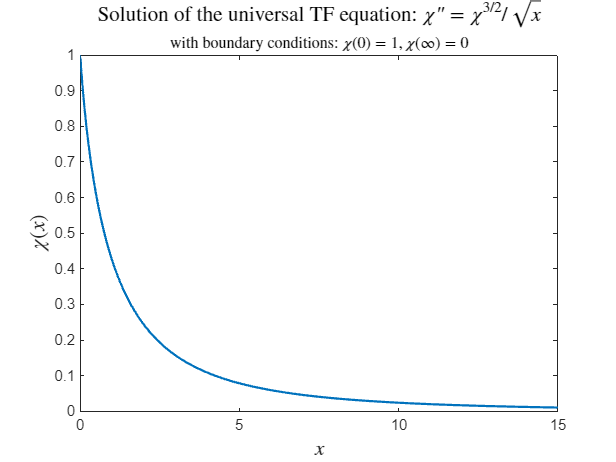

chi = real(sol.y(1,:));  % we use real to kill spurious imaginary terms that are ~1e-19
x = sol.x;  % solver returns a new (its own) mesh sol.x, check this mesh, it is not uniformly spaced
plot(x,chi)
xlabel("$x$",'Interpreter','latex',FontSize=14)
ylabel("$ \chi(x)$",'Interpreter','latex',FontSize=14) 
title('Solution of the universal TF equation: $\chi"=\chi^{3 / 2}/{\sqrt{x}}$','Interpreter','latex',FontSize=14)
subtitle('with boundary conditions: $\chi(0)=1, \chi(\infty)=0$','Interpreter','latex')
xlim([0,15])

Uncomment 3 lines below to save values of $x$ and $\chi$ in a structure variable `TFchi` (as a TFchi.mat file) that you can load from the live script on *Orbital-Free DFT*.

% TFchi.x=x;
% TFchi.y=chi;
% save TFchi

Next we specify $Z$ for a neutral atom and plot the radial electron density of a neutral atom $4\pi \rho_{_{TFNA}}(r) r^2$, using Eqs. (35) and (32).

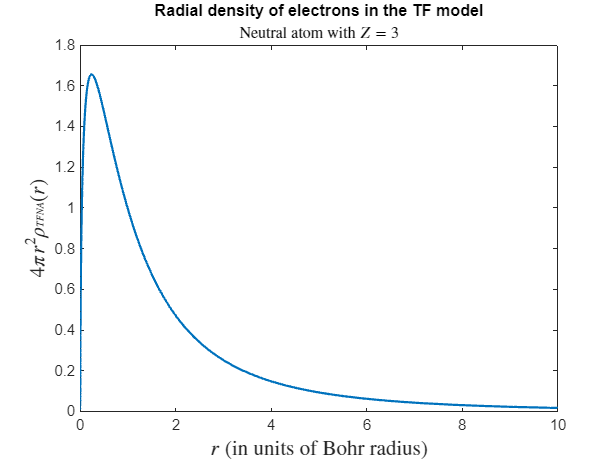

Z=3; 
Cf=3/10*(3*pi^2)^(2/3);                  % define C_F 
rho_r_x = 32/9/pi^3*(chi./x).^(3/2)*Z^2; % Eq. (35) rho_r_x = rho(r(x))
alpha=Z^(1/3)*(4*pi)^(2/3)*3/(5*Cf);     % define alpha  
r_x = x/alpha;                           % define r(x), i.e. r in terms of x as in Eq. (32)
plot(r_x, 4*pi*rho_r_x.*r_x.^2);
xlim([0, 10]);
title("Radial density of electrons in the TF model")
subtitle(['Neutral atom with $Z=$',num2str(Z)],'Interpreter','latex')
xlabel("$r$ (in units of Bohr radius)",'Interpreter','latex',FontSize=14)
ylabel("$ 4\pi r^2\rho_{_{TFNA}}(r)$",'Interpreter','latex',FontSize=14)

### Checking density normalization

For electron density in neutral atom with $N=Z$ that is described by the TF density profile $\rho_{_{TFNA}}(\mathbf{r})$ we have:


$$4\pi \int_0^{\infty} \rho_{_{TFNA}}(r ) r^2 dr/Z=1. \qquad (36)$$


Using $r=x/\alpha$ from Eq. (32) and using Eqs. (36) and (35) we obtain


$$\int_0^{\infty} \chi^{3/2}(x)x^{1/2}dx=1. \qquad(37)$$


We will check below how accurately our numerical solution for $\chi$ and $\rho_{_{TFNA}}$ satisfy these normalization conditions Eqs. (36) and (37) using [`trapz`](https://www.mathworks.com/help/matlab/ref/trapz.html) function for integrating numerical data by trapezoid method. We also will check numerically that $\frac{d \chi(x)}{dx}\Big|_{x=0}= -\frac{4\pi}{Z\alpha}\displaystyle\int_0^{\infty} \rho_{_{TFNA}}(r )rdr$, analytical proof of which is left as Exercise 7.

trapz(x, x.^(1/2).*chi.^(3/2)) - 1         % checking Eq. (37)

ans = -0.0019

% Note x as returned by solver is not a uniformly spaced variable, check diff(x). trapz takes care of this
trapz(r_x, 4*pi*rho_r_x.*r_x.^2)/Z - 1    % checking Eq. (36)

ans = -0.0019

trapz(r_x, -4*pi*rho_r_x.*r_x)/(Z*alpha) - real(sol.y(2,1))   % checking numerically Exercise 5

ans = -6.7468e-04

Note, from Eqs. (21) and (30) we see that electron density diverges in the limit $r\to 0$, and namely $\lim_{r\to 0}\rho_{_{TFNA}} (r ) \sim1/r^{3/2}$, which is of course not the case in real atomic systems as known for sure from the exact solution of hydrogen atom. There are other obvious shortcomings in the TF model, nevertheless the TF model is one of the pearls of theoretical physics. 

## Thomas-Fermi (Ground State) Energy from Thomas-Fermi Electron Density

We suggest reader to use dimensional analysis by passing to the universal, $Z$-independent variables $x$ and $\chi$ and from Eq. (15) show that for neutral atoms $E_{TF}\equiv E[\rho_{TFNA}]=AZ^{7/3},$ where $A$ is a numerical constant. To derive value of $A$, we will treat $Z$ together with $N$ as continuous "macroscopic" variables of the model on which TF energy, energy of the "equilibrium state" corresponding to the TF solution of density, depends: $E_{TF}=E[\rho_{_{TF}}]=E_{TF}(N,Z)$. We showed already that for a neutral atom $\mu=\mu_{_{NA}}=0$ and hence from the energy functional expression in Eq. (15) and using Eq. (18)  (see Appendix 2 for details) we obtain:


$$\delta E_{TF}=    -\int \frac{ \rho_{_{TFNA}}  (\mathbf{r})}{r} d \mathbf{r} \delta Z+  \mu_{_{NA}} \delta N =  -\int \frac{\rho_{_{TFNA}}(\mathbf {r})}{r} d \mathbf{r} \delta Z. \qquad (38)$$


Consequently, for a neutral atom in TF theory, since $E_{TF}(N=0,Z=0)=0$ (indeed for $N=0$ we have $\rho_{TF} = 0$), we get:


$$\begin{array}{cc}\begin{array}{rll}E_{TF} (N=Z,Z) &=-\int_0^Z\left[\int \frac{\rho_{_{TFNA}}(\mathbf{r})}{r} d \mathbf{r}\right]  \delta z=-4 \pi \int_0^Z \left[\int^{\infty}_0 \frac{ \rho_{_{TFNA}}(r(x))}{\alpha^2}  xd x \right]  \delta z \\& =-(3 / 7)(1.1295...)\left[\chi^{\prime}(\infty)-\chi^{\prime}(0)\right] Z^{7 / 3}\simeq-0.77 Z^{7 / 3}.\end{array}& \qquad (39)\\ \end{array}$$


For deriving the second line of Eq. (39) we used Eq. (35). We also used lower case letter $z$ for the dummy integration variable to distinguish it from the upper bound of the integral (upper case $Z$) in the first line of Eq. (39). Hence, we should use $z$ instead of $Z$ in Eq. (32) for $\alpha$ (hence $\alpha=1.1295...z^{1/3}$) and in Eq. (35) for $\rho_{_{TFNA}}$. In Exercise 6 we calculate the TF energy numerically and confirm result of Eq. (39) to a good accuracy.

In live script on *Orbital-Free DFT*, when putting von Weizsäcker correction and exchange-correlation terms to zero, we will solve the TF model fully numerically (using finite radial grid, and conjugate-gradient method of minimization of energy) and determine TF electron density and TF energy. We will also see there that TF result of energy $-0.77Z^{7/3}$ will get modified to $-0.64Z^{7/3}$ for large, but realistic values of $Z>20$, after inclusion of von Weizsäcker correction and exchange-correlation terms. Results presented here for the TF model will serve as a benchmark test for our orbital-free DFT numerical code, allowing us evaluation of its accuracy.

Since for one-electron system the last term in Eq. (15)  does not make any sense (nonphysical self-interaction contribution constitutes $100\%$ of the Hartree interaction for $Z=1$), TF expression produces the greatest (relative) error for $Z=1$, value of $\simeq -0.77$Ha for hydrogen atom, that is $54\%$ lower than the exact ground state energy. For helium, the TF energy is a slightly better value than what independent electron approximation gives, yet it is $35\%$ lower than true ground state energy. TF ground state energy expression Eq. (39) becomes asymptotically exact, as it captures correctly the leading $Z$ dependence of the ground state energy of an atom for $Z\to \infty$ [1].

## ** Exercises**

**Exercise 1:** Derive Eq. (9) explicitly for $N=2$ and $N=4$ cases, starting from the definition of the one-body ground state density matrix:


$$\rho_0\left(\mathbf{r}, \mathbf{r'}\right)=N\sum_{\sigma, \sigma'}\int \Psi_0^*(\mathbf{r}, \mathbf{r}_2,\cdots \mathbf{r}_N) \Psi_0(\mathbf{r'}, \mathbf{r}_2,\cdots \mathbf{r}_N) d\mathbf{r}_2\cdots d\mathbf{r}_N,$$


by representing the $N$-electron ground state wave function in terms of the Slater determinant:


$$\Psi_0\left(\mathbf{r}_1, \mathbf{r}_2, \cdots \, \mathbf{r}_N\right)=\frac{1}{\sqrt{N !}} \left|\begin{array}{cccccccccccccc}\psi_1\left(\mathbf{r}_1\right) & \psi_2\left(\mathbf{r}_1\right) & \cdots & \psi_N\left(\mathbf{r}_1\right) \\\psi_1\left(\mathbf{r}_2\right) & \psi_2\left(\mathbf{r}_2\right) & \cdots & \psi_N\left(\mathbf{r}_2\right) \\\vdots & \vdots & \ddots & \vdots \\\psi_1\left(\mathbf{r}_N\right) & \psi_2\left(\mathbf{r}_N\right) & \cdots & \psi_N\left(\mathbf{r}_N\right)\\ \end{array}\right|.$$


$\psi_m(\mathbf{r}_j)$ are the ortho-normalized plane-wave spin-orbitals that include both coordinate and spin parts: $\psi_m(\mathbf{r}_j)=\phi_m(\mathbf{r}_j) |\sigma_m\rangle_j$. Coordinate part $\phi_m(\bf{r})$ are plane-waves, like in Eq. (7), with the lowest $\mathbf{ k}$-value states occupied in the ground state by pairs of electrons (with spin up and spin down components), consistent with the Pauli (Aufbau) principle. Plugging the Slater determinant in the definition of one-body density matrix and using the orthonormalization properties of the plane-waves,$\displaystyle\int_V \phi^*_i(\mathbf{r}) \phi_j(\mathbf{r} )d\mathbf{r}=\delta_{i,j}$, obtain Eq. (9): 


$$\rho_0\left(\mathbf{r}, \mathbf{r'}\right)=\displaystyle\sum_{\sigma, \sigma'}N\int \Psi_0^*(\mathbf{r}, \mathbf{r}_2,\cdots \mathbf{r}_N) \Psi_0(\mathbf{r'}, \mathbf{r}_2,\cdots \mathbf{r}_N) d\mathbf{r}_2\cdots d\mathbf{r}_N =2 \sum_{i=1}^{N/2 } \phi^*_i\left(\mathbf{r}\right) \phi_i\left(\mathbf{r'}\right).$$


**Exercise 2:** Prove that $\chi(0)=1$ but based on normalization condition $\displaystyle\int_0^{\infty} \rho_{_{TFNA}}(r )r^2dr=Z/4\pi$. Hint: use Eq. (37) and  Eq. (33) and integration by parts. Then Eq. (37) should lead to $\displaystyle\int_0^{\infty} \frac{d}{dx} \Big( \frac{d \chi(x)}{dx} x\Big) dx-\int_0^{\infty} \frac{d \chi(x)}{dx}  dx=1$, hence $\chi(0)=1$. Alternatively, $\mu=0$ leads to $\chi(0)=1$, that in its turn implies $N=Z$, showing that $\mu(N=Z)=0$.

**Exercise 3: **Show that $\nabla^2 \Big( \frac{\tilde \chi(r)}{r}\Big)=\frac{1}{r}\frac{d^2 \tilde \chi(r)}{d r^2} -4 \pi \tilde \chi(0)\delta^3(\mathbf{r})$. 

Hint: $\nabla^2  \Big( \frac{\tilde \chi(r)}{r}\Big)=\lim_{\varepsilon \to 0}\frac{1}{r^{2}} \frac{\partial}{\partial r}\left(r^{2} \frac{\partial}{\partial r}\right)  \Big( \frac{\tilde \chi(r)}{\sqrt{r^2+\varepsilon^2}}\Big) =\frac{1}{r}\frac{d^2 \tilde \chi(r)}{d r^2} -4 \pi \tilde \chi(0)\delta^3(\mathbf{r})+\lim_{\varepsilon \to 0} \frac{2\tilde \chi'(0)\varepsilon^2}{r(r^2+\varepsilon^2)^{3/2}}$ , where we used $4\pi \delta^3 (\mathbf{r}) = \lim_{\varepsilon \to 0} 3\varepsilon^2/(r^2+\varepsilon^2)^{5/2}$ and the integral over the 3D space for the last term produces $8\pi \tilde \chi'(0) \varepsilon$, hence, in the limit $\varepsilon \to 0$ it vanishes and can be safely ignored for all purposes as it is not a singular contribution, unlike the term containing the Dirac's delta-function.

**Exercise 4: **Obtain behavior of $\rho_{TFNA}( r)$ in the limit $r\to \infty$ in the TF model. Hint: assume asymptotic behavior $\chi(x)=Ax^{\nu}$ for $x\to\infty$ and using  Eq. (33) show that $\nu=-3$. For density you should obtain $\lim_{r\to \infty}\rho_{_{TFNA}} ( r)  \sim r^{-6}$, result clearly at odds with hydrogen atom's exponential decay of electron density. Using symbolic calculation we show below that one particular solution of  Eq. (33) is $\chi(x)=144/x^3$, however it does not satisfy left boundary condition: $\chi(0)=1$. Hence $\chi(x)=144/x^3$ gives us only the asymptotic, $x\to \infty$, behavior of our true solution.

syms xx chi(xx) 
assume(xx,"positive")
chi(xx)=144/xx^3;
simplify(diff(chi,xx,2)-chi^(3/2)/sqrt(xx))

$$ans(xx) = 0$$

**Exercise 5: **Plot $4\pi \rho_{_{TFNA}}(r) r^2$ - the radial electron density dependence on $r$ for different values of $Z$ together in the same figure. Note that neither $x$ nor $\chi(x)$ carry dependence on $Z$ (due to this very reason $x$ and $\chi(x)$ were introduced) and $\rho_{TFNA} \sim Z^2$ from Eq. (35). Hence, since $r=x/\alpha = xZ^{-1/3}/1.1295...$, we have: $4\pi \int \rho_{_{TFNA}}(r) r^2 dr=Z$, (see Exercise 2). 

**Exercise 6: **Determine the Thomas-Fermi energy numerically using numerically obtained $\rho_{_{TFNA}}( r)$ and Eq. (15)  for different values of $Z$ and compare results with $-0.77Z^{7/3}$.

Hint: Pass to spherical coordinates. To simplify calculation of electron-electron repulsion energy $E_{ee}$, orient (rotate) the coordinate system so that the z axis is directed along the $\mathbf{r_1}=(r_1,\theta_1,\phi_1)$ vector and then angle between $\mathbf{r_1}$ and $\mathbf{r_2}=(r_1,\theta_2, \phi_2)$ vectors will be $\theta_2$. Calculate the distance between the two electrons in this coordinate system, remembering that distance does not depend on the orientation of the coordinate system. Then, when integrating over $\theta_2$ use: 

 
$$\int_0^{\pi} \frac{\sin{\theta_2}}{|\mathbf{r_1}-\mathbf{r_2}|} d \theta_2 = \int_0^{\pi} \frac{\sin{\theta_2}}{\sqrt{r_1^2+r_2^2-2r_1r_2\cos{\theta_2}}} d \theta_2=\frac{r_1+r_2-|r_1-r_2|}{r_1r_2}=  \begin{cases} 2/r_1,& \text{if } r_1\geq r_2\\ 2/r_2 , &  \text{if }  r_1<r_2 \end{cases}$$


to obtain:


$$E_{ee}= \frac{1}{2} \int\int \frac{\rho_{_{TFNA}} \left(\mathbf{r}_1\right) \rho_{_{TFNA}}\left(\mathbf{r}_2\right)}{\left|\mathbf{r}_1-\mathbf{r}_2\right|} d \mathbf{r}_1 d \mathbf{r}_2=16 \pi^2 \int_{r_2}^{\infty} r_1\rho_{_{TFNA}}(r_1) dr_1\int_0^{\infty} r_2^2 \, \rho_{_{TFNA}}(r_2)  dr_2$$


 and finally use that $\displaystyle\int_{r_2}^{\infty} r_1\rho_{_{TFNA}}(r_1) dr_1=-\frac{Z \alpha}{4\pi}\chi'(x=\alpha r_2)$.

 E_ee=16*pi^2*(-Z*alpha/(4*pi))*trapz(r_x, (r_x.^2).* real(sol.y(2,:)).* rho_r_x)   % electron-electron repulsion energy (positive contribution)

E_ee = 3.3275

 T_TF=Cf*4*pi*trapz(r_x,r_x.^2.*rho_r_x.^(5/3))  % kinetic energy (positive contribution)

T_TF = 9.9582

  E_en=-Z*4*pi*trapz(r_x,r_x.*rho_r_x)           % electron-nucleon attraction energy (negative contribution)

E_en = -23.2517

 E= E_ee+T_TF+E_en;
 fprintf("for Z =%d, E = %.4f Ha = %.4f eV ", Z, E, E* 27.2114 );

for Z =3, E = -9.9660 Ha = -271.1893 eV 

3/7*1.1295*real(sol.y(2,1))*Z^(7/3)  % TF energy in hartree from Eq. (39)

ans = -9.9607

**Exercise 7:** Show that $\frac{d \chi(x)}{dx}|_{x=0}= -\frac{4\pi}{Z\alpha}\displaystyle\int_0^{\infty} \rho_{_{TFNA}}(r )rdr$.

**Exercise 8:** Show the relation $\rho_{_{TFNA}} (\mathbf{r};N=Z,Z)=\rho_{_{TFNA}} (Z^{1/3}\mathbf{r};N=1,1)$ using Eqs. (35) and (32). This means that radius of the atom in the TF model (e.g. distance from the nucleus where function $4\pi \rho (r ) r^2$ has a peak) scales as $Z^{-1/3}$. Confirm last statement numerically by plotting $4\pi \rho_{_{TFNA}} (r ) r^2$ for different values of $Z$ and observing how the peak moves with changing $Z$.

## **Appendix 1**

Here we provide details for constrained optimization problem and passing to "Lagrange" functional. Instead of "canonical" we passed to "grand canonical" description, which allowed us to forget about the constraint of fixed number of particles during variation of densities. Constraint is reinstated at the end via determining proper value of $\mu$ for a given $N$:


$$\mathcal{L} [\rho]=E [\rho]-\mu (N [\rho]-N), \qquad (A1)$$
  

where $E[\rho]$ is given in Eq. (15) and $N[\rho]$ can be read from the normalization condition Eq. (16) as 


$$N[\rho] =\int \rho(\mathbf{r}) d\mathbf{r}. \qquad (A2)$$
 

$\mu$ is a Lagrange multiplier, that becomes function of total number of electrons $N$, determined from $\partial {\cal L} / \partial \mu=0$. Observe the difference between an integer number $N$ - a total number of electrons and a functional $N[\rho]$ given in Eq. (A2).

It is obvious that minimization of functional $\mathcal{L}[\rho]$ in Eq. (A1) with a density profile that satisfies Eq. (17) (i.e. by the TF density profile $\rho_{TF}(\mathbf{r})$), together with $\partial {\cal L} / \partial \mu=0$, imply minimization of energy functional given in Eq. (15) with the same density profile $\rho_{TF}(\mathbf{r})$ normalized according to Eq. (16), hence

$E[\rho_{TF}]= \min \Bigl\{ E[\rho]$: $\rho(\mathbf{r})\ge 0$, $\int \rho(\mathbf{r}) \mathrm{d} \mathbf{r} =N \Big \} \equiv E_{TF}(N) \qquad (A3).$

## **Appendix 2**

Here we give details of calculating variation of the Lagrange functional that we introduced in Eq. (A1). Variation of the Lagrange functional with the variation of electron density near the TF density profile $\rho_{_{TF}}(\mathbf {r}) \to\rho_{_{TF}}(\mathbf {r}) +\delta \rho(\mathbf {r} )$ is: 


$$\delta \mathcal{L} [\rho_{_{TF}}] = \delta E [\rho_{_{TF}}]-\mu \delta N [\rho_{_{TF}}]=\int  \Big( \frac{5}{3} C_{F} \rho_{_{TF}}^{2 / 3}(\mathbf{r})-\frac{Z}{|\mathbf{r}|}+\int \frac{\rho_{_{TF}}\left(\mathbf{r}^{\prime}\right)}{\left|\mathbf{r}-\mathbf{r}^{\prime}\right|} d \mathbf{r}^{\prime} -\mu \Big) \delta \rho(\mathbf{r}) d\mathbf{r}=0 \qquad (A4).$$


The last equality is due to Eq. (17) and $\delta N[\rho_{_{TF}}]= \delta N[ \mathrm{ at \, any}\, \rho]= \displaystyle \int  \delta \rho(\mathbf{r}) d\mathbf{r}$.

Hence, using Eqs. (A3) and (A4), we can **directly relate** variation of the TF (ground state) energy to variation of the total number of electrons:


$$\delta E_{TF} = \delta E[\rho_{_{TF}}]=\mu \delta N \to \mu(N) =\frac{\partial E_{TF}}{\partial N}. \qquad(A5)$$


Note, since the ground state energy is an ordinary function and not a functional of $N$, the statement that $\mu$ is rate of change of $E_{TF}$ with $N$ means $\mu =\partial E_{TF}/\partial N$. If $N$ is the only global variable in the model, hence $Z$ is not allowed to vary, then partial differential is equivalent to total differential. 

If we, in addition to $N$, allow variation of $Z$ too, then the ground state energy becomes function of $Z$ as well and:

  
$$\delta E_{TF} (N,Z) =\mu \delta N -\int \frac{\rho_{_{TF}}(\mathbf{r})}{r} d \mathbf{r} \delta Z,   \qquad (A6)$$


where  

$\mu (N,Z)=\Big(\frac{\partial E_{TF}}{\partial N} \Big)_Z$ and $\displaystyle \int \frac{\rho_{_{TF}}(\mathbf{r})}{r} d \mathbf{r} =-\Big(\frac{\partial E_{TF} }{\partial Z}\Big)_N. \qquad (A7)$

For neutral atoms $\mu(N=Z,Z) = \mu_{_{NA}}=0$ for any $Z$ and Eq. (A6) boils down to Eq. (38).

## Helper Functions

#### **Constructing ode**

First we define TF ode Eq. (33) for our numerical solver. We write as:  


$$\begin{cases} y(1)&=&\chi \\ y(2)&=& \chi'   \end{cases}$$


in order to represent second order ode Eq. (33) as a pair of first-order equations:


$$\begin{cases} y'(1)&=&y(2)\\ y'(2)&=& y^{3/2}(1)/\sqrt{x}   \end{cases}$$


function dydx = thomasfermi(x,y)
dydx = [y(2) 
        y(1).^(3/2)/sqrt(x)];  
end

#### Defining boundary condition for numerical solver

First ($x_0$) and last ($x_{\inf}$) points of the initial mesh is automatically recognized as boundary points by the solver. We represent boundary conditions as: 


$$\begin{cases} y(x_0)-1&=&0 \\ y(x_{inf})&=& 0   \end{cases}$$


function res = boundary(ya, yb)
res=[ya(1)-1    % ya(1)=y(x_0), whereas ya(2)=y'(x_0)
     yb(1)];    % yb(1)=y(x_inf)
end

#### Initial guess functions 

Finally, we provide initial guess for the function under investigation and its derivative. 

function g = guess(x)
g = [exp(-x)     % guess for y(1) = chi(x)
    -exp(-x)];   % guess for y(2) = chi'(x)
end

[*] Defining energy functional of electron density, $E[\rho]=(T+V_{ee})[\rho ]+ \int \rho (\mathbf{r})  V_{ext}(\mathbf{r}) d \mathbf{r}$, is the central idea of density functional theory. Some 4 decades after the TF model, Hohenberg and Kohn showed (and Levy and Lieb generalized) that functional $E[\rho]$ of electron density $\rho(\mathbf{r})$ (i.e. of a scalar function $\rho(\mathbf{r})$ defined on $R^3$ and obtainable from $N$-fermionic, hence antisymmetric, unit-normalizable wave-function $\Psi(\mathbf{r}_1,\mathbf{r}_2,...,\mathbf{r}_N)$: $\rho(\mathbf{r})=N\displaystyle\sum_{ \sigma}\int |\Psi(\mathbf{r},\mathbf{r}_2,...,\mathbf{r}_N)|^2 d\mathbf{r}_2...d\mathbf{r}_N$) can be defined, such that the minimal value of the functional equals the ground state energy and this value is attained for $\rho(\mathbf{r}) =\rho_0(\mathbf{r})  =\displaystyle\sum_{i=1}^{N}   \langle \Psi_0|  \delta^3 (\mathbf{\hat r}_i -\mathbf{r}) |\Psi_0\rangle$, $E[\rho_0]=\min   \Bigl\{ E[\rho]  \Bigr\}=E_0$ (where $E_0$ is the exact ground state energy of the system $\hat H|\Psi_0 \rangle=E_0|\Psi_0\rangle$). See derivation of the Hohenberg-Kohn theorems in live script *From Many-Body Wave Function Description to DFT*. 

Functional is a mapping from functions to numbers, meaning that $E[\,]$ takes a function as an input argument, here the electron density profile $\rho(\bf{r})$, and returns a number (energy in units of hartree) that depends on $\rho(\bf{r})$. 

Energy functional expression in Thomas-Fermi model given in Eq. (15) can be considered as the simplest approximation for $E[ \rho]$ for $N$- electron atom with simple kinetic energy functional $T[\rho] \to T_{TF}[\rho]$ in Eq. (14) and no account for exchange-correlation effects in electron-electron interaction, $V_{ee}[\rho] \to V_{ee}^{TF}[\rho]=E_H[\rho]$. 

## **References**

1. Elliott H. Lieb, [*A Brief Review of Thomas-Fermi Theory*](https://physics.nyu.edu/LarrySpruch/Lieb.pdf) (2000).

2. P. Hohenberg and W. Kohn, [*Inhomogeneous Electron Gas*](https://journals.aps.org/pr/pdf/10.1103/PhysRev.136.B864), Phys. Rev. B **136**, 864 (1964).